# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['/Users/REINHARTLAB/Desktop/TimeEst/TimeEst_EEG_New'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = false;  
Deci.PCom               = true;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['/Users/REINHARTLAB/Desktop/TimeEst/TimeEstEEG'];    
Deci.Retroactive = true; 

## 1. Trial Definitions

Deci.DT.Type = 'TimeEst_Definitons'; 
Deci.DT.Starts     = {10};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {11};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[28 29 30]};
Deci.DT.trlcheck = false;

Deci.DT.Locks      = [12 17 27];
Deci.DT.Toi        = [-2 3];  

Deci.DT.Displace.Static = [];
Deci.DT.Displace.Markers = {[28 29 30]};
Deci.DT.Displace.Duration =2;


## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';



## 3. Artifact Rejection

Deci.ICA.do = true;
Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.dominlength = true;
Deci.Art.RT.minlength = 200;
Deci.Art.RT.domaxlength = false;
Deci.Art.RT.maxlength = 600;
Deci.Art.RT.dotwostd = true;

Deci.Art.RT.locks = [2 1];

Deci.Art.AddComponents =  false;

## 4. Analysis

if Deci.Step == 4
    Deci.DT.Markers    = {[28 29 30] [-1 -2]};
end
Deci.Analysis.Laplace       =false;                                                               % Uses Captrak .bvct file with same name in RawData Folder
Deci.Analysis.DownSample    = 500;
Deci.Analysis.ApplyArtReject = false  ;

Deci.Analysis.ERP.do  = false;
Deci.Analysis.Freq.do  = true;

Deci_Wavelet;


Deci.Analysis.Freq.method        = 'wavelet';                                                  % Currently only uses 'wavelet' and 'hilbert'
Deci.Analysis.Freq.foi           = exp(linspace(log(1),log(50),25));                         % Frequency of Interest
Deci.Analysis.Freq.width         = exp(linspace(log(1),log(13),25));                                                         % Width

## 5. Plotting

Deci is running retroactive subjects


Running Deci for 18 subjects
 
----------------------
 
Plotting ITPC
Loading Plottor for Subject #1: TimeEst_EEG_039CG
Loading Plottor for Subject #2: TimeEst_EEG_046CG
Loading Plottor for Subject #3: TimeEst_EEG_050PS
Loading Plottor for Subject #4: TimeEst_EEG_065CG
Loading Plottor for Subject #5: TimeEst_EEG_065PS
Loading Plottor for Subject #6: TimeEst_EEG_069PS
Loading Plottor for Subject #7: TimeEst_EEG_070PS
Loading Plottor for Subject #8: TimeEst_EEG_072PS
Loading Plottor for Subject #9: TimeEst_EEG_074CG
Loading Plottor for Subject #10: TimeEst_EEG_074PS
Loading Plottor for Subject #11: TimeEst_EEG_077PS
Loading Plottor for Subject #12: TimeEst_EEG_078PS
Loading Plottor for Subject #13: TimeEst_EEG_079CG
Loading Plottor for Subject #14: TimeEst_EEG_084CG
Loading Plottor for Subject #15: TimeEst_EEG_085CG
Loading Plottor for Subject #16: TimeEst_EEG_088PS
Loading Plottor for Subject #17: TimeEst_EEG_092PS
Loading Plottor for Subject #18: TimeEst_EEG_101CG
 
Using Lock: Stim On

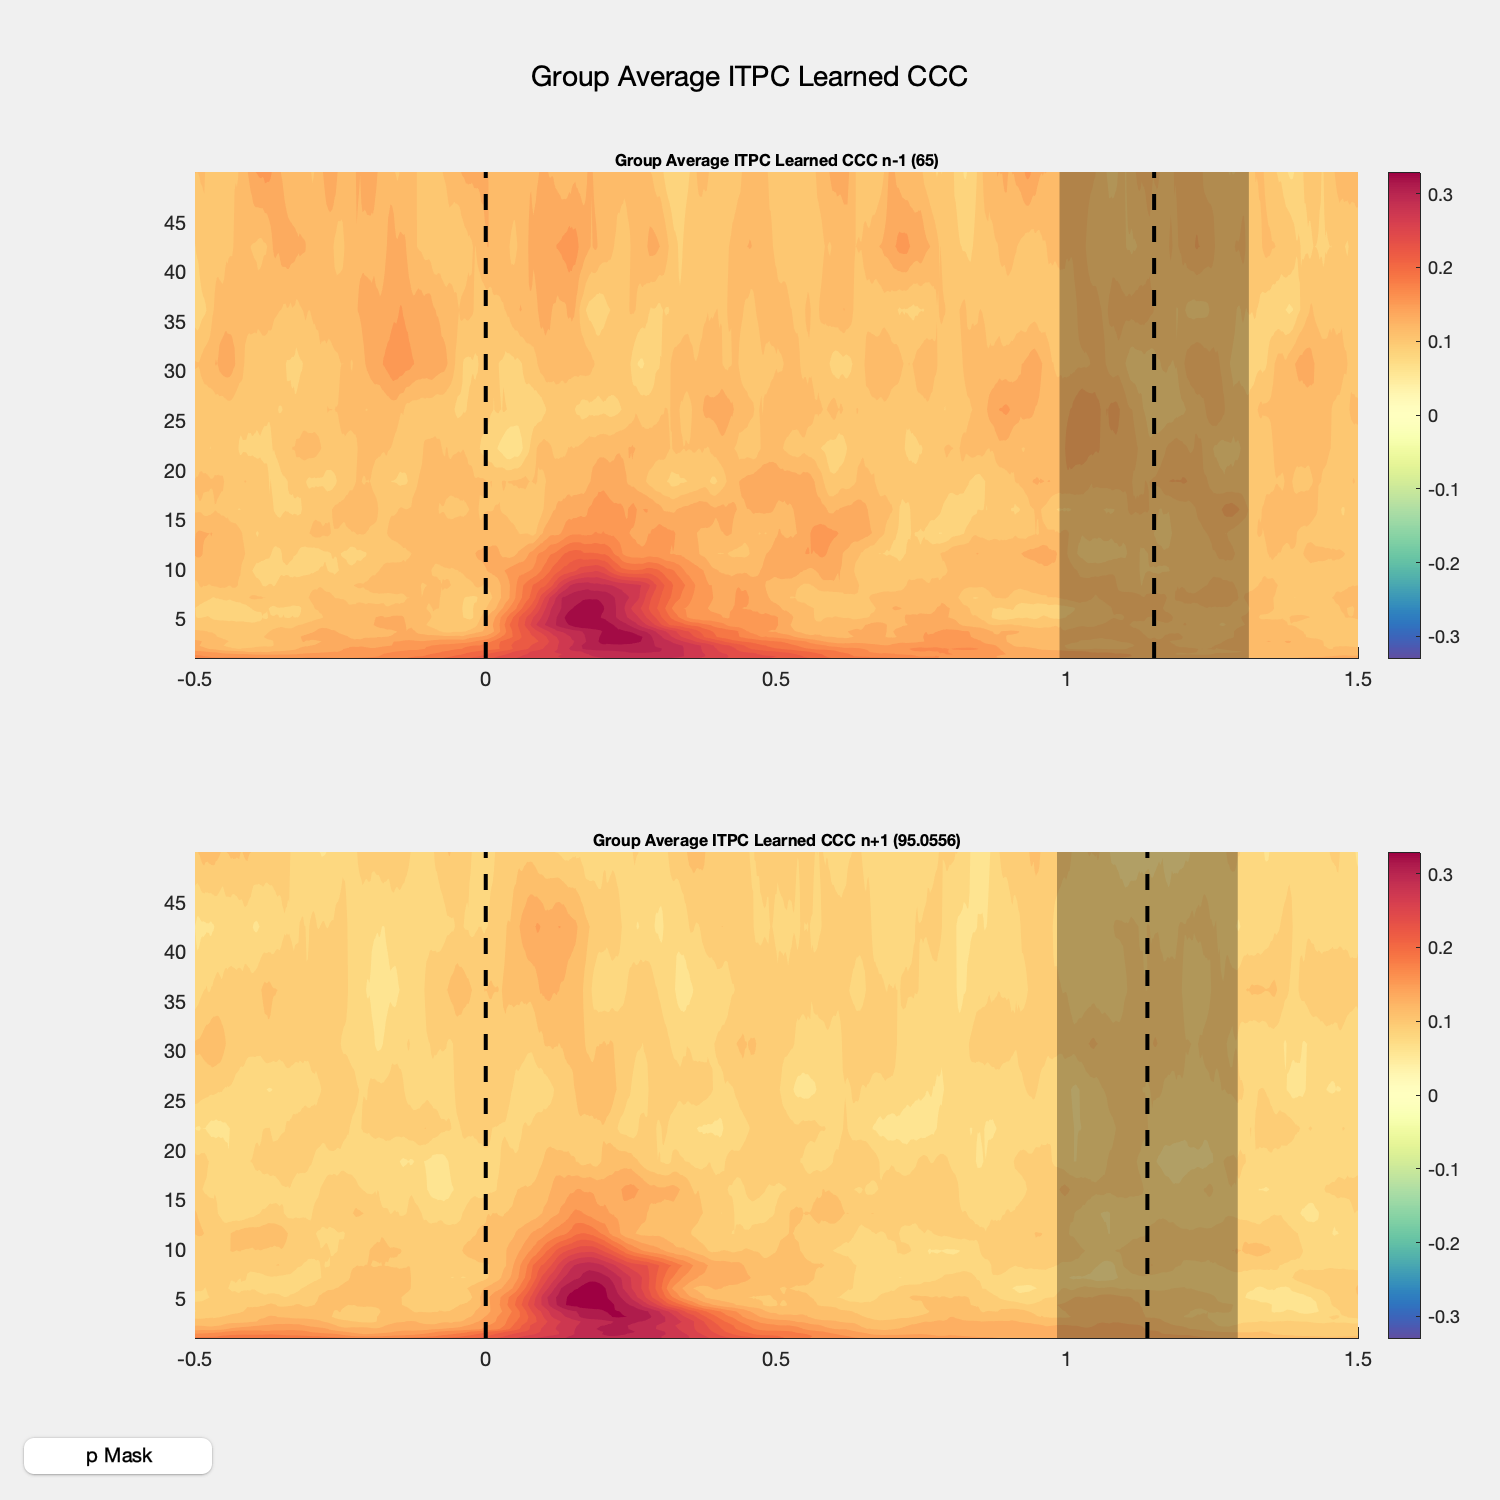

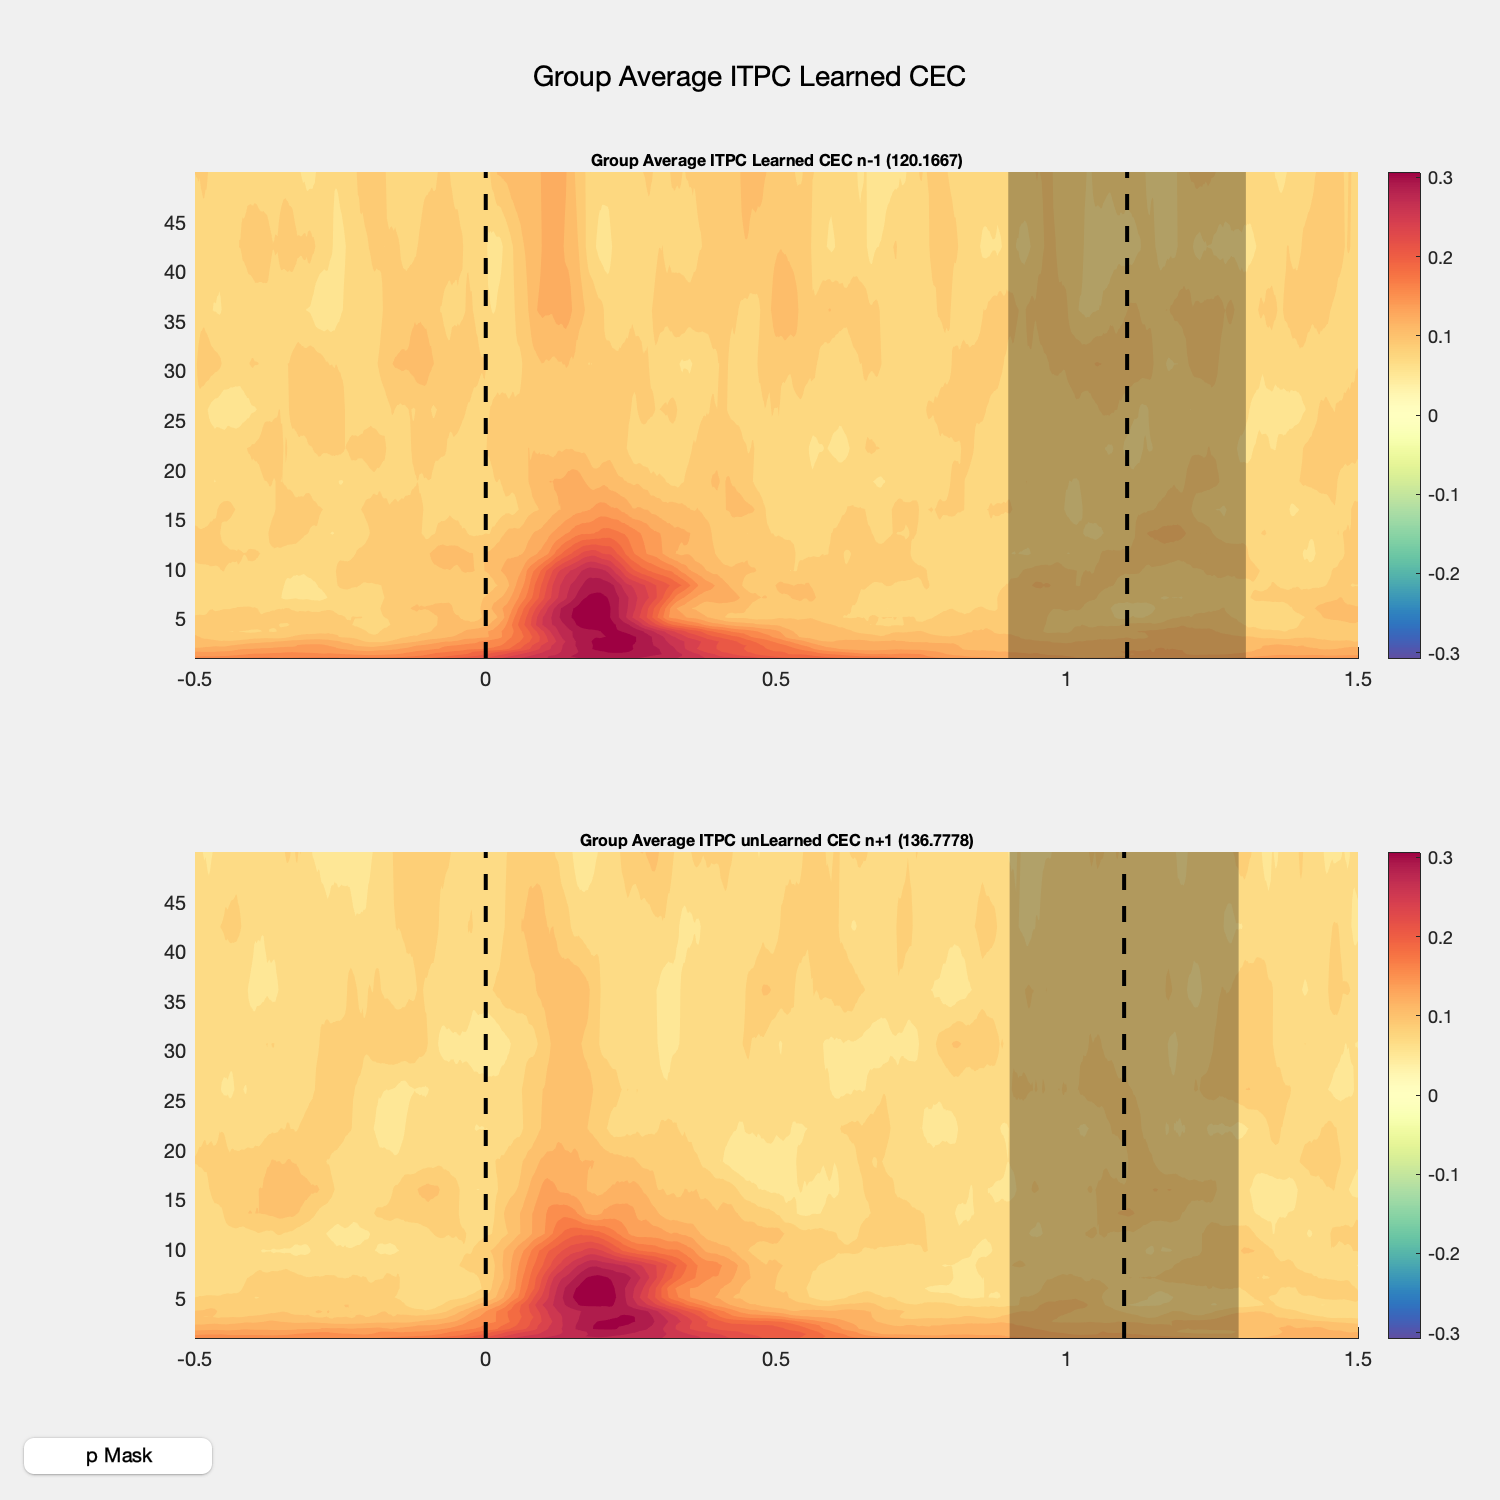

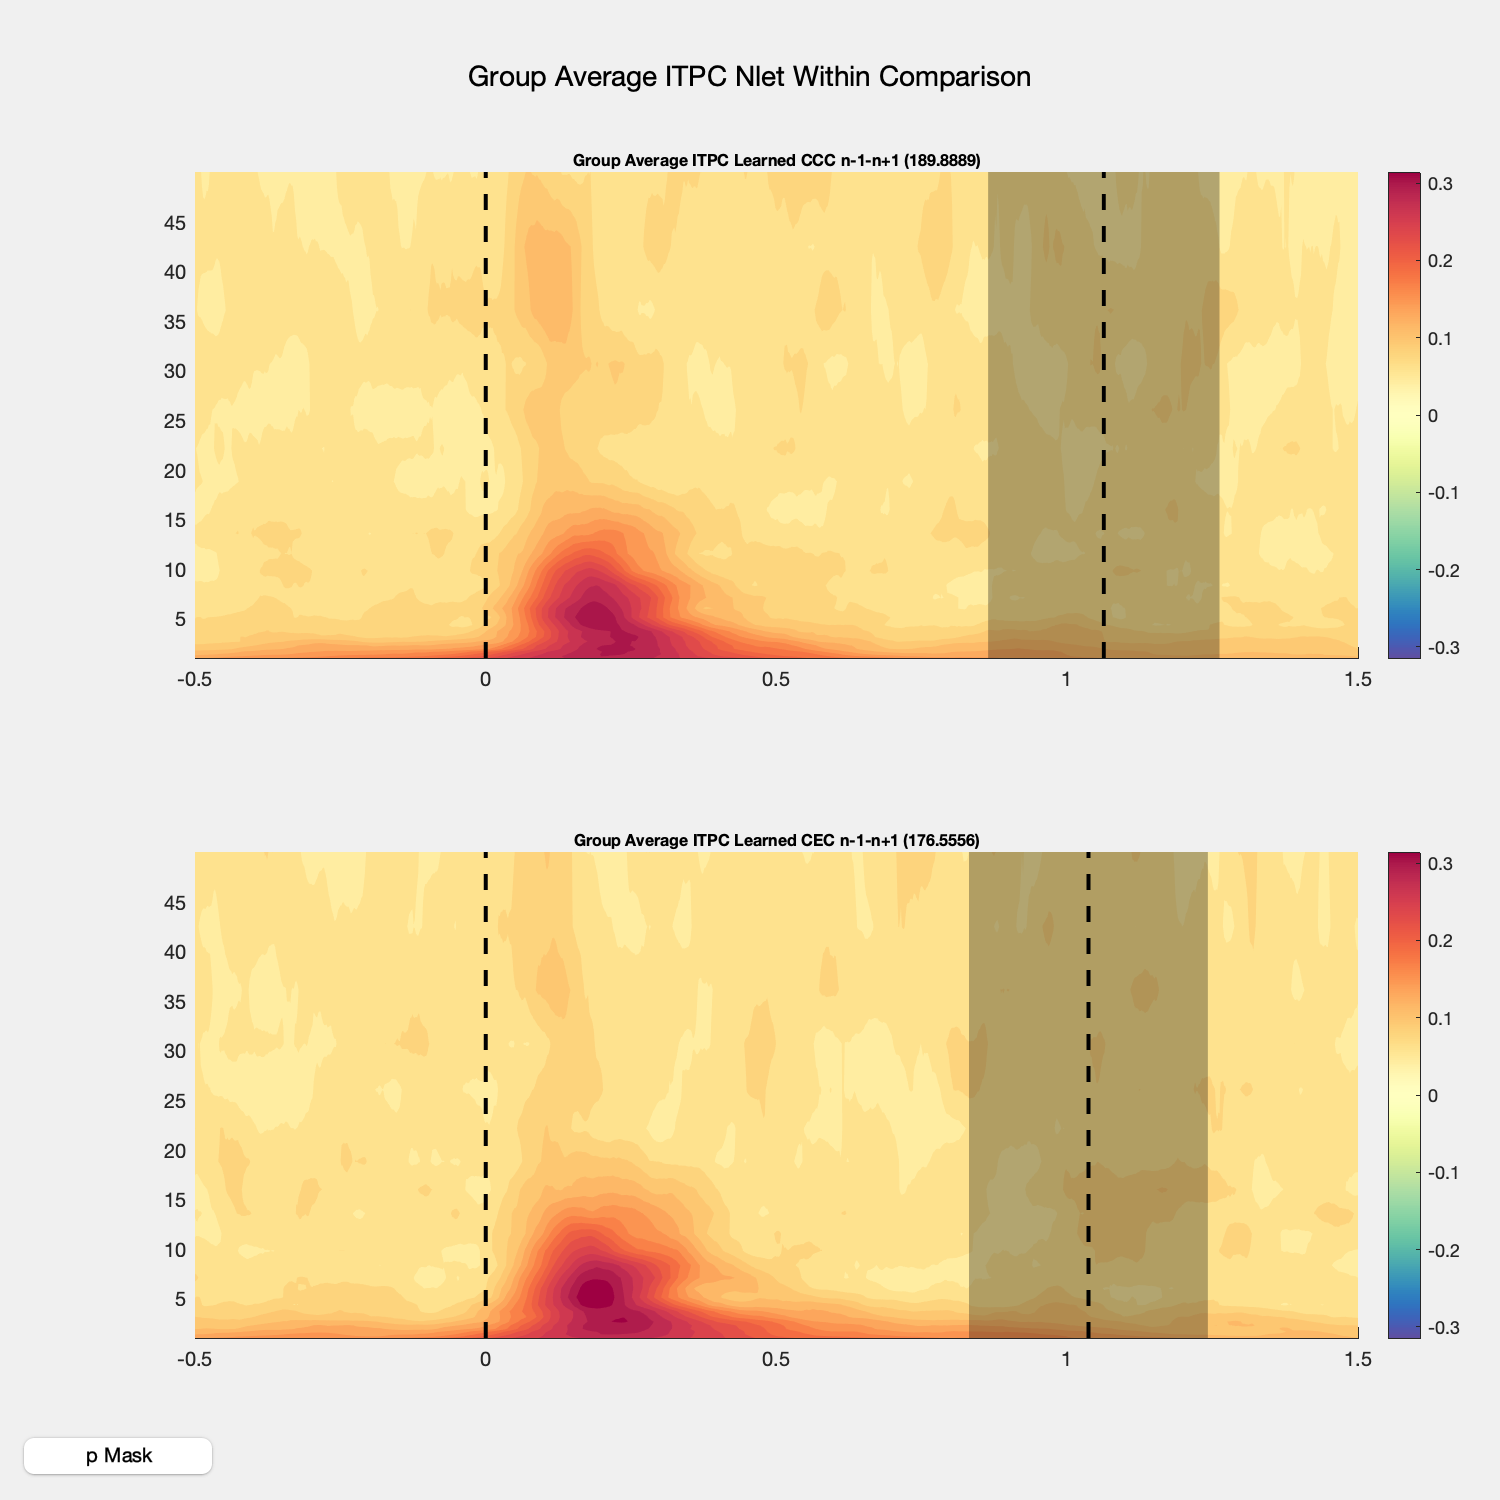

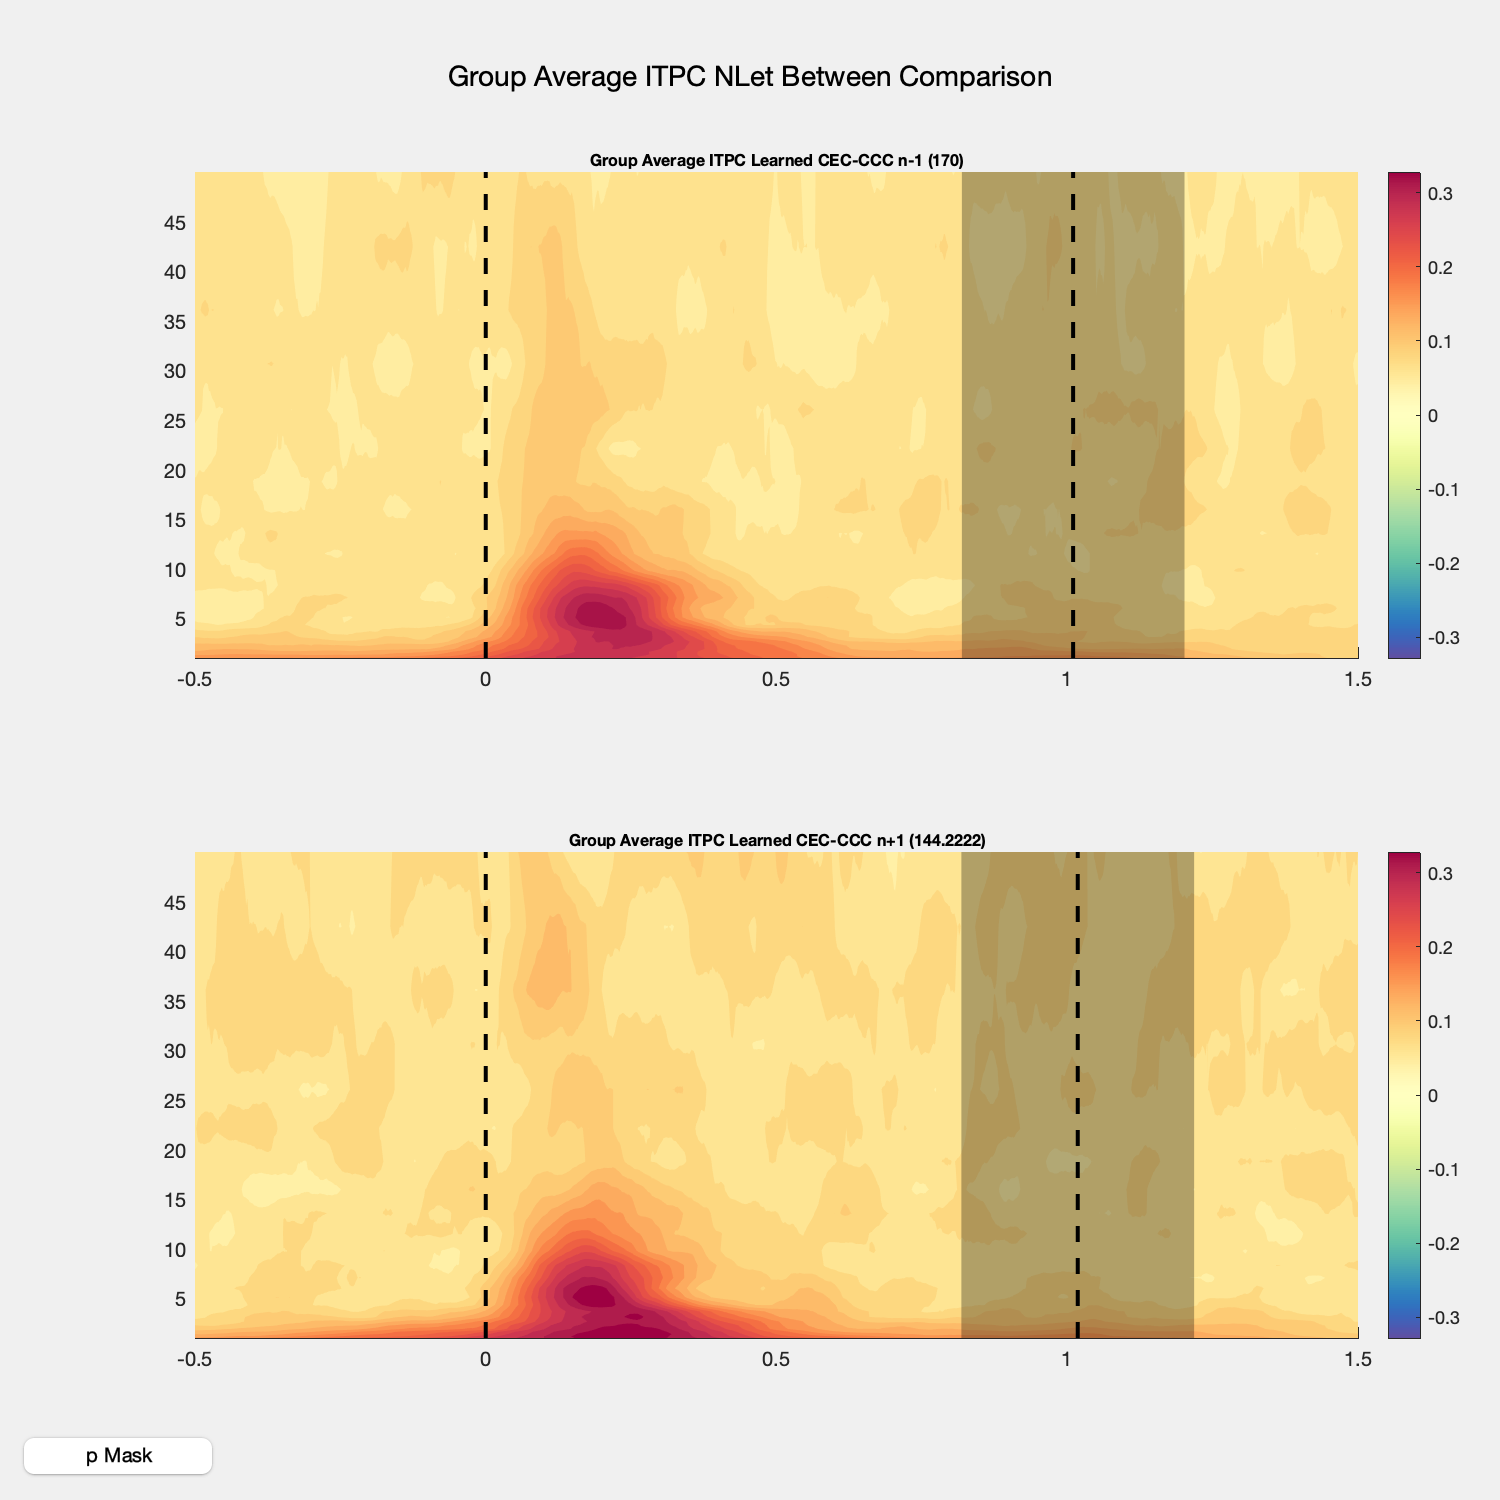


TimeEst_Triplet

Deci.Plot.BslRef = 'Stim Onset';
Deci.Plot.Lock = 'Stim Onset';
    
if  strcmpi(Deci.Plot.BslRef, 'Stim Onset')
    Deci.Plot.Bsl     = [-.5 -.3];
else
    Deci.Plot.Bsl     = [-.2 0];
end

Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.Extra = false;

Deci.Plot.Freq.Type    = 'ITPC';
Deci.Plot.BslType = 'none';

Deci.Plot = Exist(Deci.Plot,'FreqYScale','linear');

Deci.Plot.GrandAverage = true;

    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [.1 .3];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
       
    Deci.Plot.MTopo.do    =false;
    Deci.Plot.MTopo.Foi     = [13 20];                   % Frequency of Interest
    Deci.Plot.MTopo.Toi     = [0 .5];                   % Time of Interest
    Deci.Plot.MTopo.ToiSegs = 5;
    Deci.Plot.MTopo.Channel = ['Reinhart-All'];      
    
    Deci.Plot.Square.do  =true;
    Deci.Plot.Square.Foi     = [1 inf];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [];                   % Time of Interest
    Deci.Plot.Square.Channel = [{'FCz'}];                % Channel of Interest
    
    Deci.Plot.Wire.do    =false;
    Deci.Plot.Wire.Foi     =   [9 13];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Wire.Channel = {'FCz'};              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [5 7.5];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     = [.11 .13];                   % Time of Interest
    Deci.Plot.Bar.Channel =  {'FCz'};            % Channel of Interest
    
    
    if Deci.Plot.Square.do
        Omnibus = false;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            Deci.Plot.BslType = 'relchange';
            Deci.Plot.Stat.FPlots =  false;
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.correctm = 'no';
        end
        Deci.Plot.Stat.FPlots =  false;
        
    elseif Deci.Plot.Topo.do 

        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    elseif Deci.Plot.Wire.do
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
    elseif Deci.Plot.Bar.do
        Deci.Plot.Stat.do = false;
    end
    
    Deci.Plot.Stat.twoway.do = false;
    
    Deci_Backend(Deci);